clear
% How many samples to measure?
t_sample = 10; %[s]
f_measurement = 4000; %[Hz]
N_samples = t_sample * f_measurement;

% Model should be Reference_model_Control_Engineering or change it if you renamed the
% model
ModelName = 'Reference_model_Control_Engineering';
% Check if the model is running, makes no sense to measure otherwise.
if ~strcmp(get_param(ModelName,'SimulationStatus'),'external')
   warning('The model is not running, can not perform a measurement.');
   return
end
% Get the noise block
BlockPaths = find_system(ModelName);
% Get the correct string
Index_noise = find(contains(BlockPaths,'Noise'));
% If we have more than 1 index, this means duplicate blocks, should not
% happen! Give a warning, and then try to trigger the first.
if length(Index_noise) > 1
    warning('There appear to be duplicate noise blocks in your model. Please remove all duplicate blocks.');
    Index_noise = Index_noise(1);
end

fprintf(['Starting measurement with white noise on the disturbance.\n',...
    'If you are planning on doing an FRF measurement, \n',...
    'think carefully about the signals you need and consider open/closed loop.\n']);

% Set the variance of the noise to 0.1
set_param(BlockPaths{Index_noise},'variance','0.1');
pause(0.1);

% Do the measurement
% How many signals do you need to record?
N_signals = 2;
measurement = SPERTE_Measure_And_Collect(p,N_signals,N_samples,ModelName);
pause(0.1);

% Turn of the noise
set_param(BlockPaths{Index_noise},'variance','0')

% By default the two signals being logged into the Measurement Block 
% are d and y
% Input
d = measurement(:,1);
% Output
y = measurement(:,2);


% Plot the measurement
figure(1); clf(1);
stairs(d); hold on; stairs(y);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');

%data analysis
fs = f_measurement %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

t_end = N_samples/fs

t_end = 10


%removing uselss data 
N_trash = 1000; 
u = u(N_trash:end)

u =    -0.0322
   -1.9235
   -1.6267
    0.0606
   -0.0804
   -1.5121
   -1.5789
   -1.6647
   -0.3032
    0.2659


d = d(N_trash:end)

d =     0.8938
   -0.9828
   -0.6810
    0.8557
    0.5037
   -0.9812
   -0.9922
   -0.9536
    0.5442
    1.4011


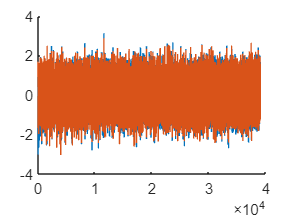


%window settings
min_freq = 0.1*2*pi; %[rad/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = nfft/2;


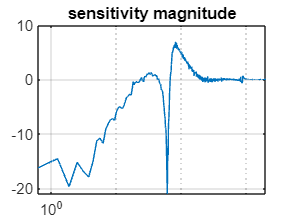

%Tf estimate
[Sud, F] = tfestimate(d,u,hann(nfft),round(nfft/2),nfft,fs); %cross spectral power density
Sdd = pwelch(d,hann(nfft)); %spectral power disturbance
Suu = pwelch(u,hann(nfft)); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud;
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on

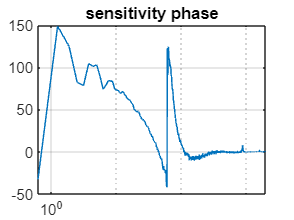


semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on

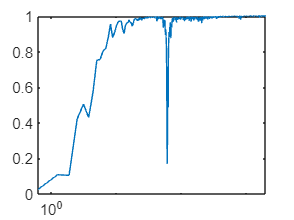


%plotting coherence 
[coherence_ry, f] = mscohere(d,u,hann(nfft),[],nfft,fs);
semilogx(f,coherence_ry)

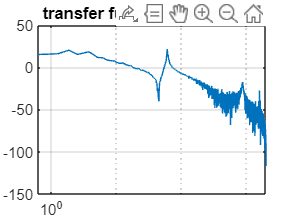

title('coherence')
grid on 
    
%plotting open loop transfer function
L = 1./S - 1;
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on

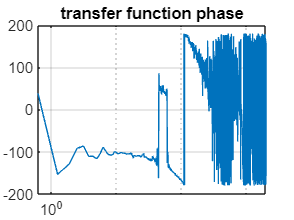


semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on